# Analysing neural recordings using the Brain Observatory Toolbox

## Overview

The Brain Observatory Toolbox (BOT) is a Matlab package for conveniently working with neural imaging data provided by the Allen Brain Observatory ([http://observatory.brain-map.org/visualcoding/](http://observatory.brain-map.org/visualcoding/)). The BOT helps you search and filter the many experimental data sets; download and manage the data; and provides useful methods to assist in analysing neural responses and behavioural data.

This tutorial provides a demonstration of filtering and selecting experimental data, and characterising neural responses to visual stimuli in mouse V1. Neural response properties such as orientation tuning are quantified, along with basic behavioural analysis.

The BOT has been made available by The University of Hampshire and the Mathworks, and is provided under a BSD license.

## Installing the toolbox

You can install the Brain Observatory Toolbox either by cloning the source repository or downloading a release from github ([https://github.com/emeyers/Brain-Observatory-Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox)); or by installing the BOT as a package from the Mathworks File Exchange ([https://www.mathworks.com/matlabcentral/fileexchange/66276-emeyers-brain-observatory-toolbox](https://www.mathworks.com/matlabcentral/fileexchange/66276-emeyers-brain-observatory-toolbox)).

**From github**

Clone the Brain Observatory Toolbox repository using `git`, or download a release from github as a `.zip` file. Add the base directory to the `matlab` path; *do not* add the package directory `+bot` to the matlab path.

**From the File Exchange**

Visit the BOT page on File Exchange (link), and click the "install package" button (XXX).

## Additional requirements

Some aspects of the toolbox make use of accelerated `.mex` files, and therefore require `mex` to be configured. These files will be compiled automatically when needed; if `mex` is not available, then `matlab` native versions will be used.

## Privacy information

We track the usage of this toolbox along with some demographics using the Google Analytics API, for us to understand the demand for the toolbox.

## Getting started

The toolbox classes are contained within the `bot` namespace within matlab. Once the toolbox is added to the `matlab `path, you can access the main classes:

`bot.sessionfilter` — Retrieve and manage lists of available experimental sessions, filtering them by various experimental parameters.

`bot.session` — Encapsulate, manage and access data for a single experimental season.

We'll go through the usage of these classes during the tutorial. Right now we need to initialise the toolbox and download the initial manifest of experiments provided by the Allen Brain Observatory. The BOT only downloads what data is necessary, beginning with the experimental metadata. The neural recordings are quite large, and so raw data for experiments is only downloaded when it is needed for analysis. All data is transparantly cached by the toolbox to save network bandwidth.

**Range of data available**

The Brain Observatory project collected data from a range of mouse visual areas, at a range of imaging depths, with indicator expression produced under several transgenic lines, and using a number of visual stimuli. For detailed information about experimental conditions and stimuli, see the [Brain Observatory website](http://observatory.brain-map.org/visualcoding/).

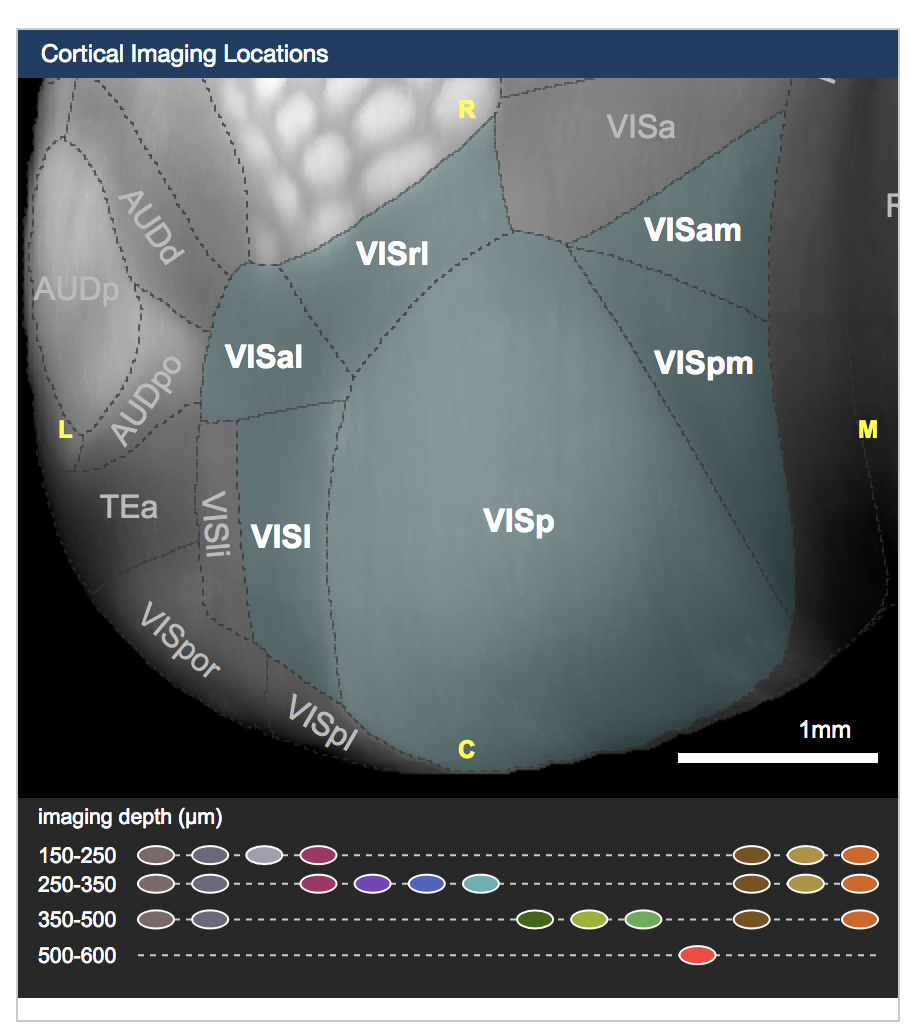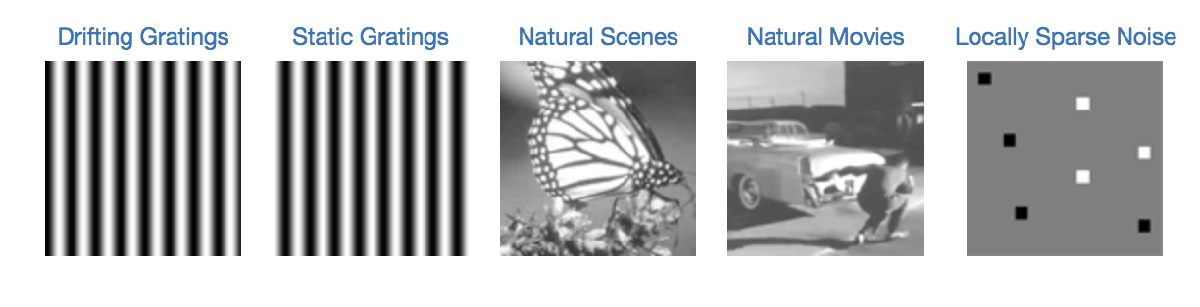

**Searching and filtering experimental data**

First let's quickly explore the range of data available. Listing, filtering and searching through the experimental data is managed by the `bot.sessionfilter` class.

bosf = bot.sessionfilter

We can look at the metadata for some of the experimental sessions contained in the `.valid_session_table` property:

head(bosf.valid_session_table)

bosf =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [543×15 table]
                  stimulus: {9×1 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [10×1 double]
              container_id: [181×1 double]
                session_id: [543×1 double]
              session_type: {4×1 cell}
                  cre_line: {6×1 cell}
        eye_tracking_avail: [2×1 logical]


In order to locate experiments of interest, we need to filter the available sessions down to just the few we want. To accomplish this, `bot.sessionfilter` provides several `filter_...()` methods:

methods(bosf)

ans = 8×15 table
     date_of_acquisition      experiment_container_id    fail_eye_tracking        id        imaging_depth              name               specimen_id      stimulus_name                                     storage_directory                                   targeted_structure_id    experiment_container    well_known_files    targeted_structure      specimen          cre_line    
    ______________________    _______________________    _________________    __________    _____________    _________________________    ___________    __________________    ____________________________

- `filter_session_by_cre_line()` — Choose sessions that contain data only from the desired CRE driver line

- `filter_session_by_eye_tracking()` — Choose seesions that contain valid eye tracking data

- `filter_sessions_by_container_id()` — Choose sessions that match a given container ID, if you know it

- `filter_sessions_by_imaging_depth()` — Choose sessions that match a particular imaging depth

- `filter_sessions_by_session_id()` — Choose sessions matching a given session ID, if you know it

- `filter_sessions_by_session_type()` — Choose sessions matching a session type (set of stimuli; see the Brain Observatory website for details)

- `filter_sessions_by_stimuli()` — Choose sessions containing responses to desired stimuli

- `filter_sessions_by_targeted_structure()` — Choose sessions where a desired brain structure was imaged

Let's begin by picking experiments from a single visual area. The method `get_all_targeted_structures` returns a list of the visual areas available in the database:

bosf.get_all_targeted_structures()


Methods for class bot.sessionfilter:

clear_filters                                          get_all_session_types                                  
filter_session_by_cre_line                             get_all_stimuli                                        
filter_session_by_eye_tracking                         get_all_targeted_structures                            
filter_sessions_by_container_id                        get_filtered_sessions                                  
filter_sessions_by_imaging_depth                       get_summary_of_containers_along_depths_and_structures  
filter_sessions_by_session_id                          get_summary_of_containers_along_imaging_depths         
filter_sessions_by_session_type                        get_summary_of_containers_along_targeted_structures    
filter_sessions_by_stimuli                             get_targeted_structure_acronyms                        
filter_sessions_by_targeted_structure                  get_total_num_of_c

Primary visual cortex is named `'VISp'` in the Brain Observatory data set. We can now filter the experimental sessions to only those recorded in primary visual cortex:

bosf.filter_sessions_by_targeted_structure('VISp')

ans = 6×1 cell array
    {'VISal'}
    {'VISam'}
    {'VISl' }
    {'VISp' }
    {'VISpm'}
    {'VISrl'}


 There are now 138 experiments remaining out of the original 543. Let's filter further by selecting experiments that contain drifing grating responses:

bosf.get_all_stimuli

ans =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [138×15 table]
                  stimulus: {9×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: [6×1 double]
              container_id: [46×1 double]
                session_id: [138×1 double]
              session_type: {4×1 cell}
                  cre_line: {6×1 cell}
        eye_tracking_avail: [2×1 logical]


bosf.filter_sessions_by_stimuli('drifting_gratings')

bosf.filter_sessions_by_session_id(527745328)

ans = 9×1 cell array
    {'drifting_gratings'        }
    {'locally_sparse_noise_4deg'}
    {'locally_sparse_noise_8deg'}
    {'natural_movie_one'        }
    {'natural_movie_three'      }
    {'natural_movie_two'        }
    {'natural_scenes'           }
    {'spontaneous'              }
    {'static_gratings'          }


## Get a single experimental session

The method `.get_filtered_sessions()` returns the identified sessions as `bot.session` objects. These are smart wrappers for the experimental data, which at first only hold the metadata for each experimental session. The raw data will only be downloaded when it is needed.

bos = bosf.get_filtered_sessions()

ans =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [46×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: [6×1 double]
              container_id: [46×1 double]
                session_id: [46×1 double]
              session_type: {'three_session_A'}
                  cre_line: {6×1 cell}
        eye_tracking_avail: [2×1 logical]


bos.get_metadata()

The `session` object provides a number of methods to access the experimental data. These methods generally match the Brain Observatory API.

methods(bos)

ans =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [1×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: 275
              container_id: 527550471
                session_id: 527745328
              session_type: {'three_session_A'}
                  cre_line: {'Cux2-CreERT2'}
        eye_tracking_avail: 0


- `get_max_projection()` — Return an image of the maximum intensity projection of the fluorescence data

- `get_dff_traces()` — Return fluorescence traces from individual cells after demixing,  neuropil correction and dF/F0 conversion

- `get_pupil_location()` — Return the time trace of estimated pupil locations during the experiment

- `get_pupil_size()` — Return the time trace of estimated pupil size during the experiment 

- `get_running_speed()` — Return the time trace of running speed exhibited by the animal during the experiment

## Examine an overview of the imaging data

Let's look at the imaged field, by visualizing the maximum intensity projection of the data. By examining the session metadata we can see that the field of view is 400x400µm (512x512 pixels). We can plot a scale bar appropriately.

fPixelSize = 400/512;

bos =   session with properties:

               sSessionInfo: [1×1 struct]
    strLocalNWBFileLocation: '/Users/dylan/Development/Brain-Observatory-Toolbox_GIT/+bot/Cache/external/neuralcoding/prod12/specimen_517650091/ophys_experiment_527745328/527745328.nwb'


vfXLoc = linspace(0, 400-fPixelSize, 512) + fPixelSize / 2;

ans = struct with fields:
                        age: '112 days'
                        sex: 'female'
              imaging_depth: '275 microns'
         targeted_structure: 'VISp'
        ophys_experiment_id: 527745328
    experiment_container_id: 527550471
              device_string: 'Nikon A1R-MP multiphoton microscope. CAM2P.1 Please see http://help.brain-map.org/display/observatory/Allen+Brain+Observatory for details'
          excitation_lambda: '910 nanometers'
                  indicator: 'GCaMP6f'
                        fov: '400x400 microns (512 x 512 pixels)'
                   genotype: 'Cux2-CreERT2/Cux2-CreERT2;Camk2a-tTA/wt;Ai93(TITL-GCaMP6f)/Ai93(TITL-GCaMP6f)'
         session_start_time: 'Fri Jul  8 09:29:58 2016'
               session_type: 'three_session_A'
              specimen_name: 'Cux2-CreERT2;Camk2a-tTA;Ai93-244896'
               generated_by: {4×1 cell}
                   cre_line: 'Cux2-CreERT2/Cux2-CreERT2'
           imaging_depth_um: 275
          

figure;
imagesc(vfXLoc, vfXLoc, bos.get_max_projection());


Methods for class bot.session:

EnsureCached                                get_metadata                                get_session_type                            
get_cell_specimen_ids                       get_motion_correction                       get_spontaneous_activity_stimulus_table     
get_cell_specimen_indices                   get_neuropil_r                              get_stimulus                                
get_corrected_fluorescence_traces           get_neuropil_traces                         get_stimulus_epoch_table                    
get_demixed_traces                          get_pupil_location                          get_stimulus_table                          
get_dff_traces                              get_pupil_size                              get_stimulus_template                       
get_fluorescence_timestamps                 get_roi_ids                                 list_stimuli                                
get_fluorescence_traces             

colormap default;
axis square tight off;
hold all;
plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');

Helpfully, the locations and shapes of ROIs defining each neuron are supplied to us from the Brain Observatory data. We can access these ROIs using the `get_roi_mask() `method. This method returns a structure containing ROIs than can be plotted and manipulated using Matlab built-in commands.

sROIs = bos.get_roi_mask()
figure;
image(vfXLoc, vfXLoc, labelmatrix(sROIs));
axis tight square off;
hold all;
plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');

## Analysing cell responses

Now let's get access to the fluorescence traces for all ROIs, using the `get_corrected_fluroescence_traces()` method. This method returns a `[Tx1]` vector of timestamps, and a `[TxN]` matrix of fluorescence responses for each cell, at each corresponding timestamp.

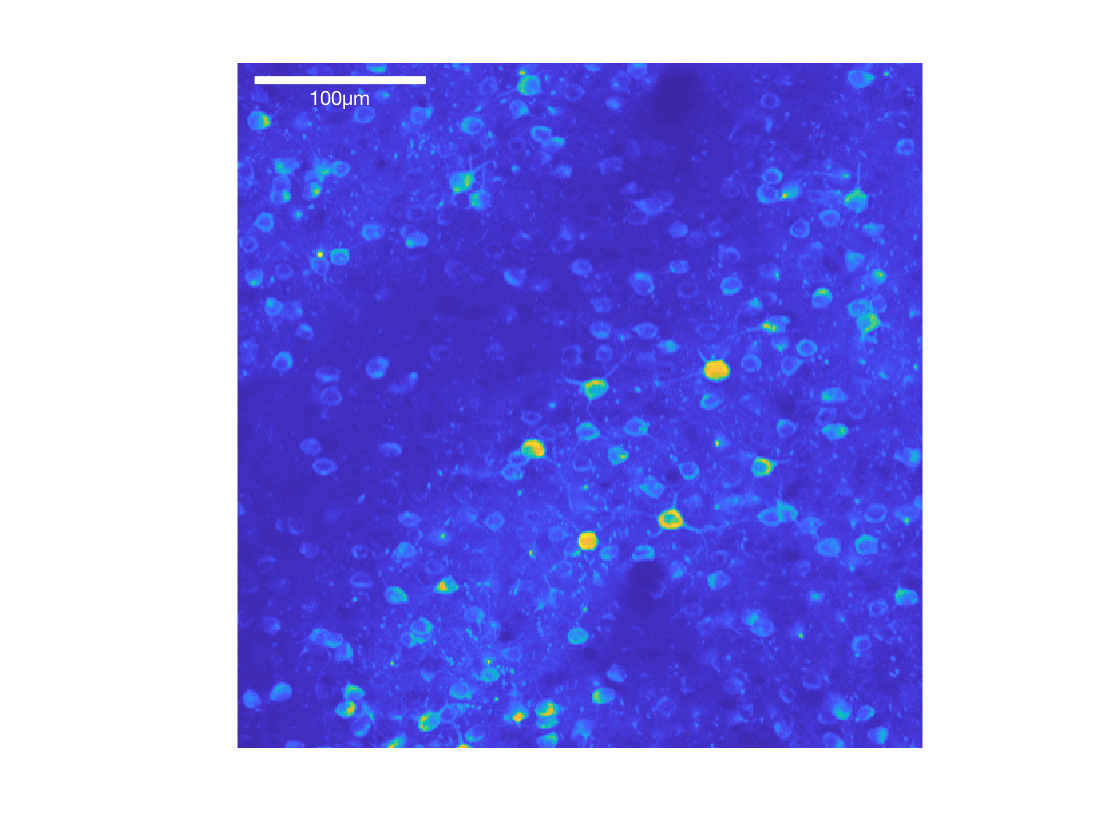

[vtTimestamps, mfTraces] = bos.get_dff_traces();

whos vtTimestamps mfTraces
figure;
plot(vtTimestamps, bsxfun(@plus, mfTraces(:, 1:10:end), (0:10:size(mfTraces, 2))/3))

sROIs = struct with fields:
    Connectivity: 8
       ImageSize: [512 512]
      NumObjects: 254
    PixelIdxList: {1×254 cell}
          Labels: {1×254 cell}


axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0');

Not all cells respond equally, as is clear from the traces above. One approach to select ROIs with robust responses is to measure the skewness of the individual responses over time. Healthy pyramidal cells with good quality data will respond sparsely but robustly over the course of an experiment, with strong fluorescence signals well above the imaging noise floor. These response characteristics lead to a high skewness in the response distribution. We can use the built-in Matlab `skewness()` command to estimate the skewness for each ROI.

vfSkewness = skewness(mfTraces);
figure;
histogram(vfSkewness);
xlabel('Skewness'); ylabel('Count')

Let's compare the response of a high-skewness ROI with a low-skewness ROI.

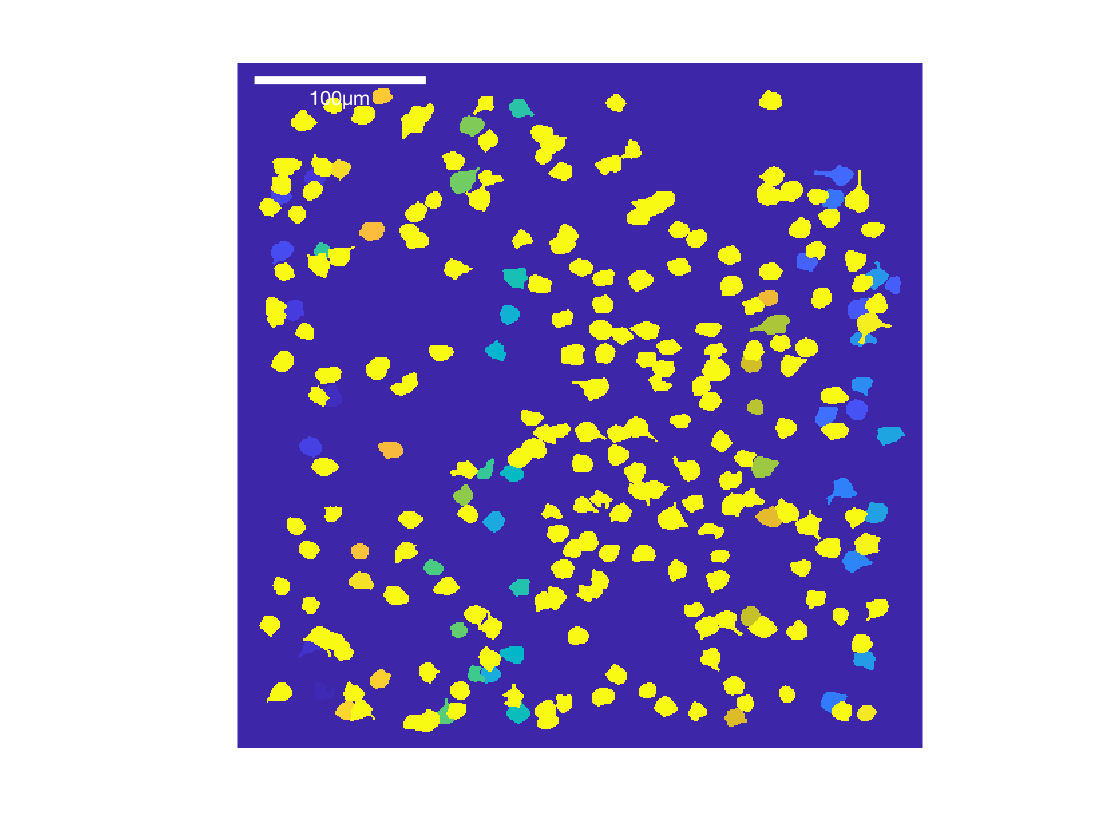

[~, vnSortOrder] = sort(vfSkewness);

plot(vtTimestamps, mfTraces(:, vnSortOrder([5 end])))
xlabel('Time (s)'); ylabel('dF/F0');

Generally a skewness threshold of 1 or 2 is sufficient, which leaves that majority of cells in this experiment.

## Analysing stimulus responses

This animal was presented with an array of stimuli, including drifting sine-wave grating stimuli. Let's find the responses to individual trials of the drifting gratings, separated by drift direction, and build tuning curves for each ROI.

First we need to access the stimulus information, using the `bos.get_stimulus_epoch_table()` method.

bos.get_stimulus_epoch_table()

This table lists the epochs during which the various stimulus paradigms were presented. `'drifting_gratings'` stimuli were presented in three blocks, from the beginning to the end of the session. To obtain the imaging frames corresponding to the individual visual stimuli, we need the `bos.get_stimulus_table()` method:

tDriftingGratings = bos.get_stimulus_table('drifting_gratings');

  Name                   Size                 Bytes  Class       Attributes

  mfTraces          115755x254            117607080  single                
  vtTimestamps      115755x1                 926042  duration              



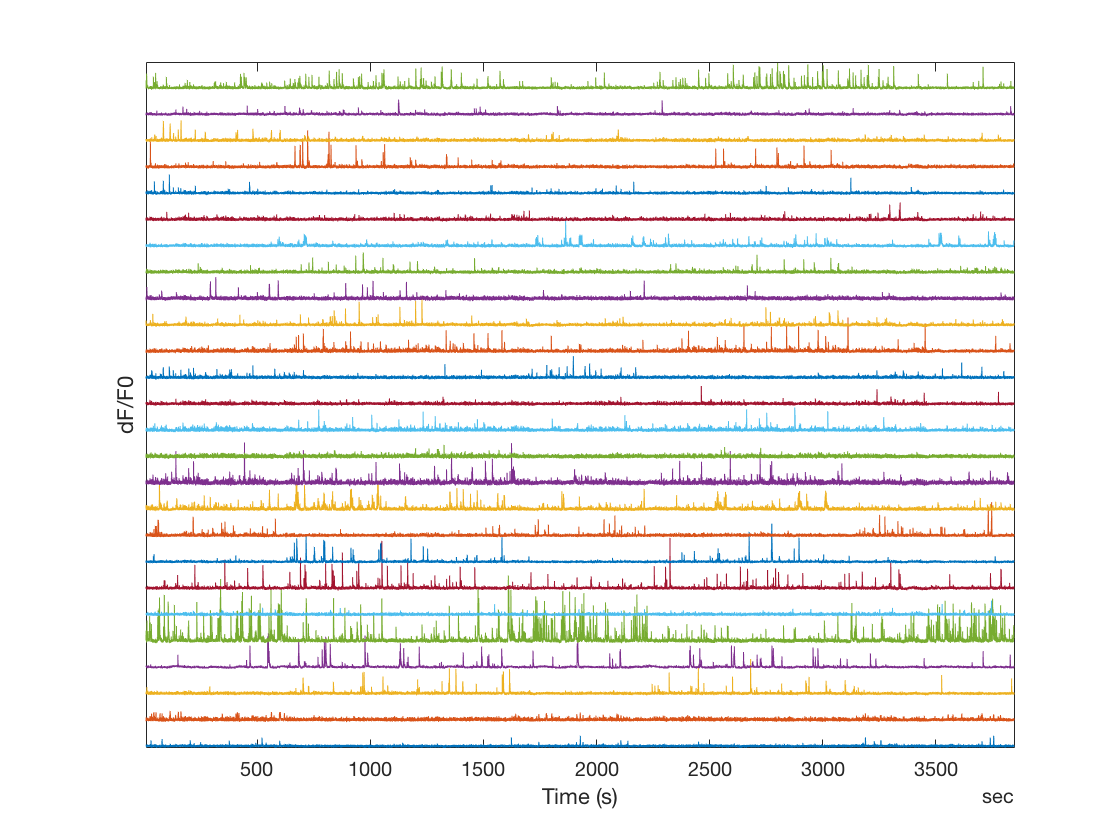

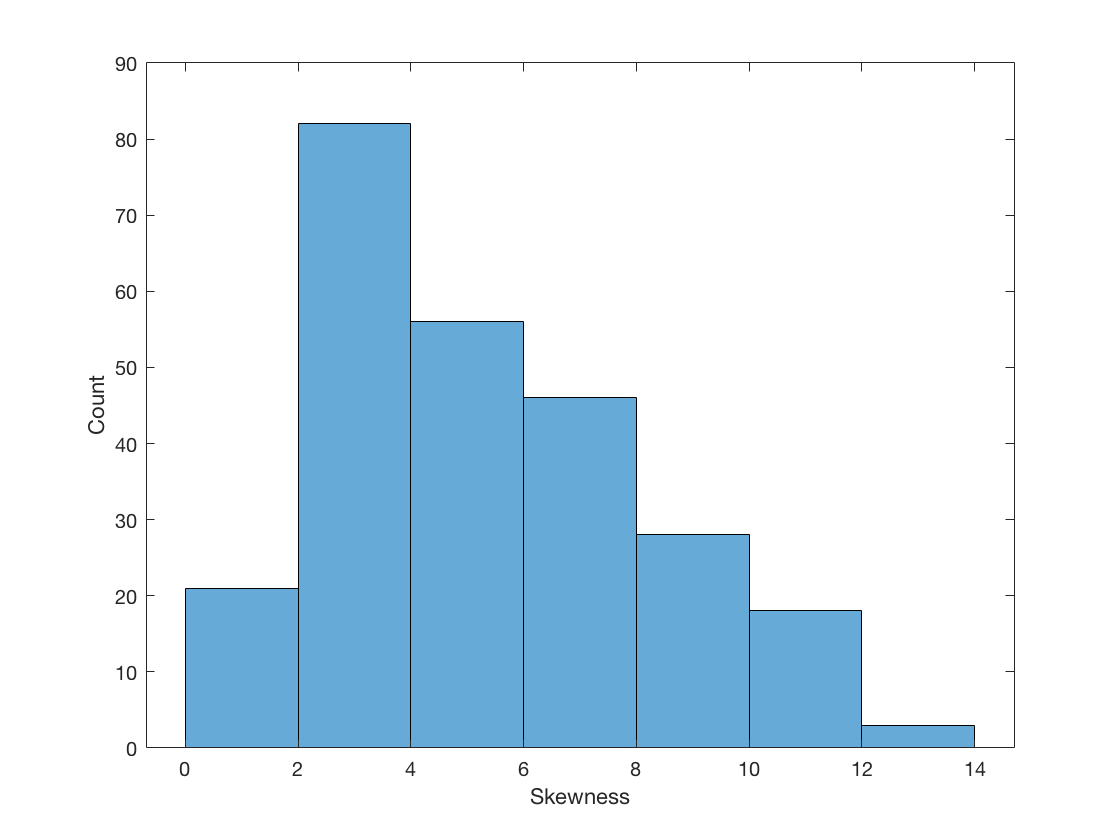

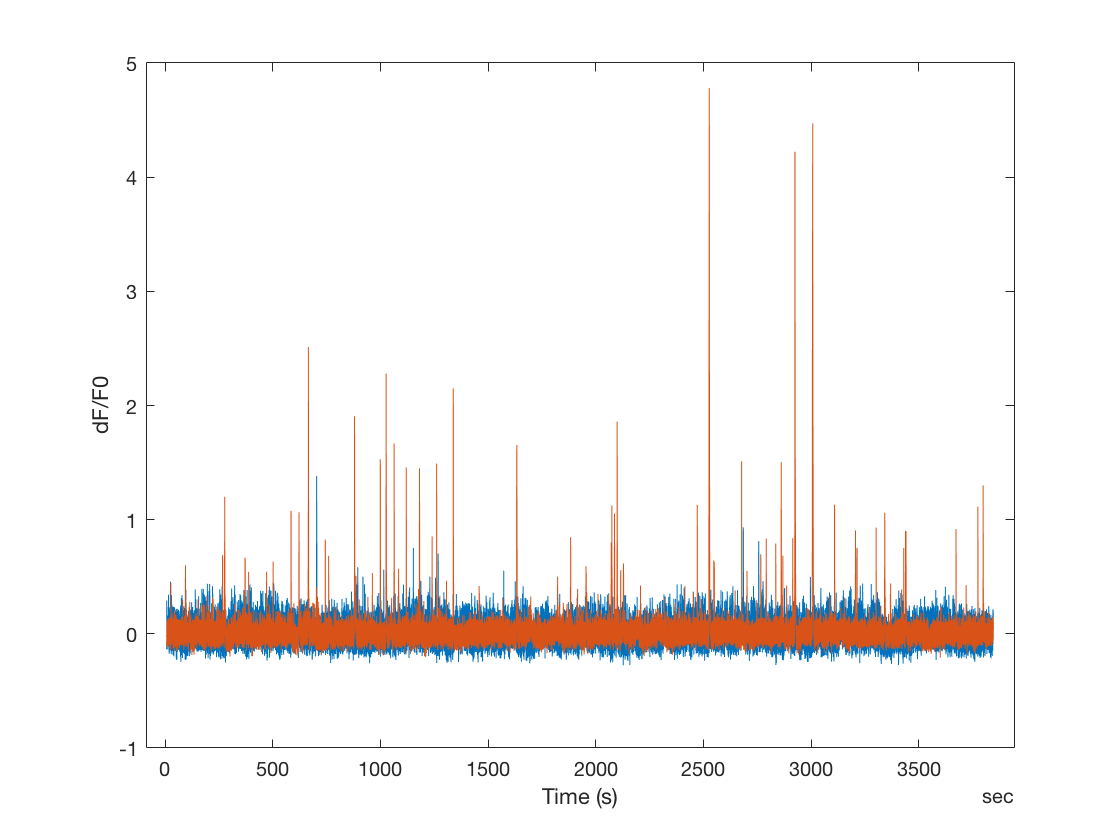

ans = 7×3 table
          stimulus           start_frame    end_frame
    _____________________    ___________    _________

    'drifting_gratings'        733           18826   
    'natural_movie_three'    19761           37864   
    'natural_movie_one'      38769           47820   
    'drifting_gratings'      48726           66804   
    'spontaneous'            66954           75884   
    'natural_movie_three'    75885           93987   
    'drifting_gratings'      94892          115498   


ans = 8×5 table
    temporal_frequency    orientation    blank_sweep    start_frame    end_frame
    __________________    ___________    ___________    ___________    _________

      1                   270            0               733            793     
      4                   315            0               824            883     
    NaN                   NaN            1               914            974     
     15                    90            0              1005           1064     
      1                   270            0              1095           1155     
     15                   315            0              1186           1245     
     15                   270            0              1276           1336     
      4                   135            0              1367           1426     


head(tDriftingGratings)

Each visual stimulus is listed in order of presentation, along with the stimulus parameters (temporal frequency, orientation) and the start and stop imaging frames that correspond to the given stimulus presentation.